# Lab6

dt = 0.01;
t = -10 : dt : 10;

## Esercizio 1 (i)

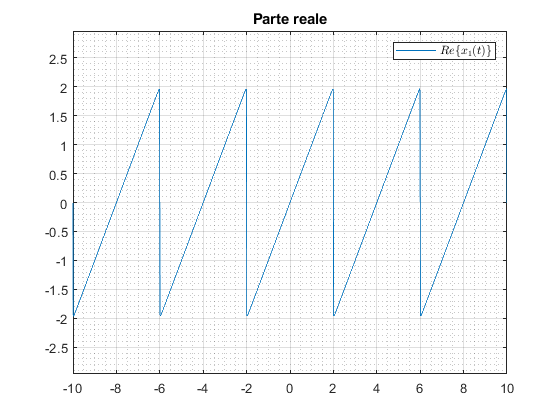

T1 = 4;
X0 = 0;
x1 = zeros(size(t)) + X0;
for k = 1:length(x1)
	x1 = x1 + 2 * (-2 / pi / k * (-1)^k) * sin(2 * pi * t * k / T1);
end
rappresentaUnSegnale(t, x1, 'x_{1}(t)');

## Esercizio 1 (ii - iii)

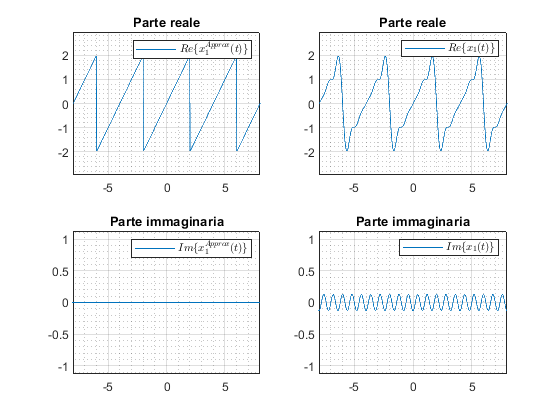

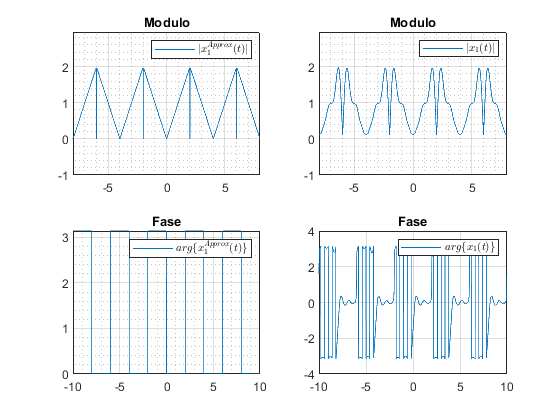

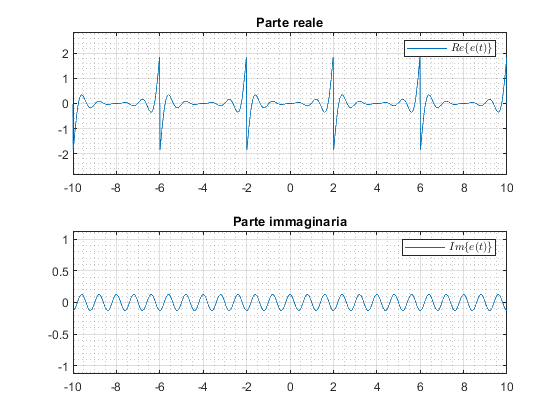

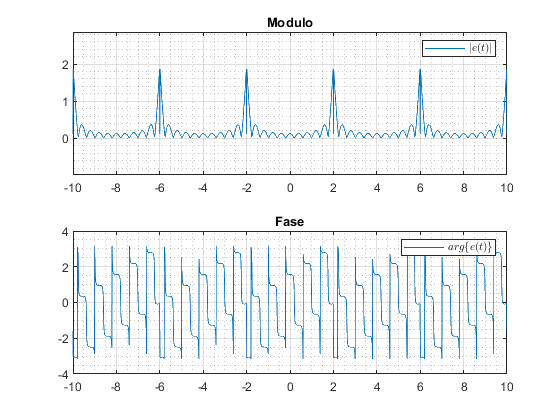

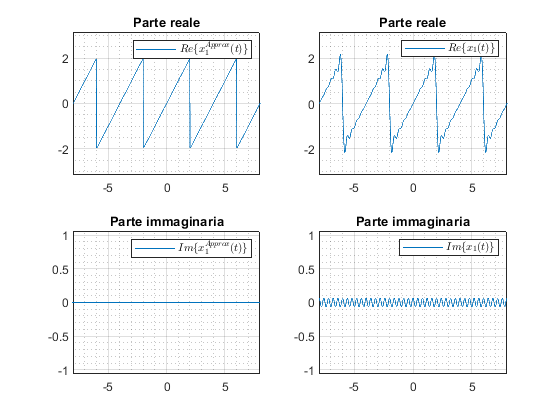

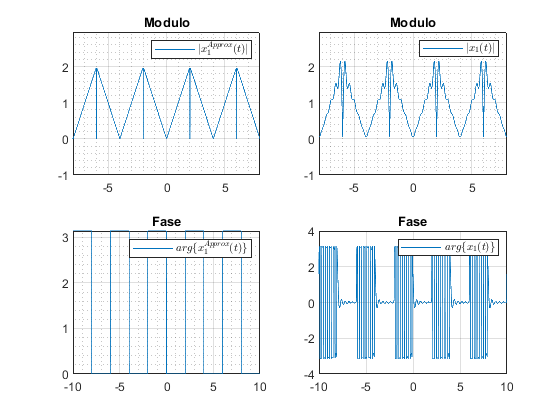

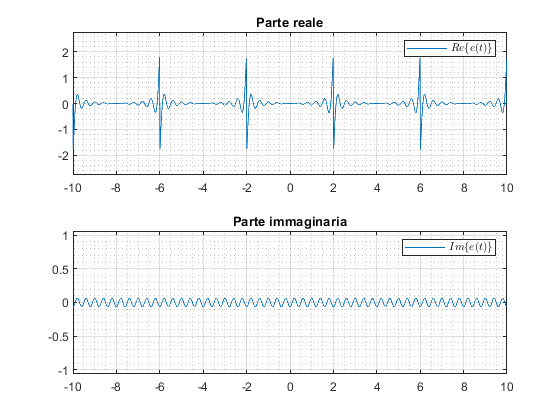

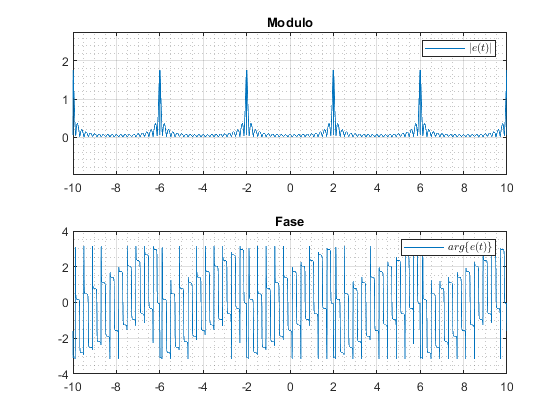

for k = 10:10:30
	x1Approx = serieDiFourier(t, x1, 4, k);
	figure;
	rappresentaDueSegnali(t, x1, x1Approx, 'x_{1}^{Approx}(t)', 'x_{1}(t)');
	err = x1 - x1Approx;
	rappresentaUnSegnale(t, err, 'e(t)');
end

## Esercizio 2 (i)

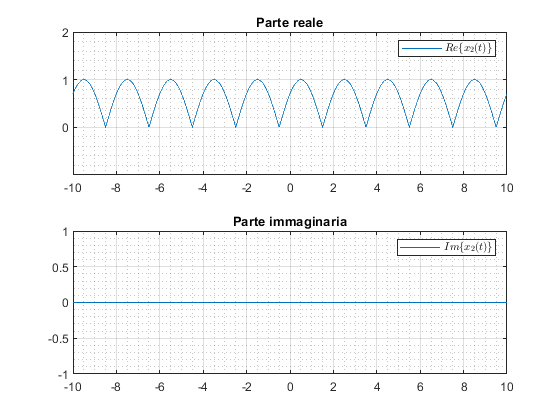

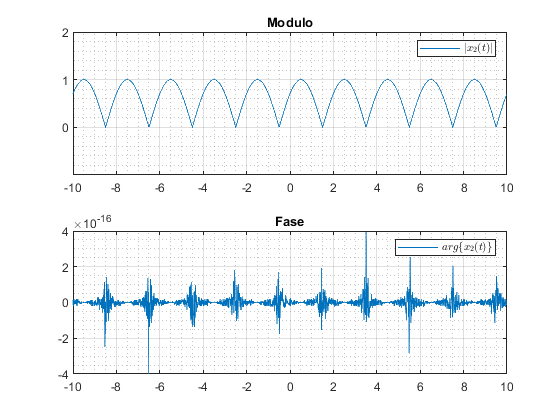

T2 = 2;
X0 = 0;
x2 = zeros(size(t)) + X0;
for k = -length(x2):length(x2)
	x2 = x2 + (2 * (-1)^(k + 1) / pi / (4 * k^2 - 1)) * exp(-1i * pi * k / 2) * exp(1i * 2 * pi * k / T2 * t);
end
rappresentaUnSegnale(t, x2, 'x_{2}(t)');

## Esercizio 2 (ii)

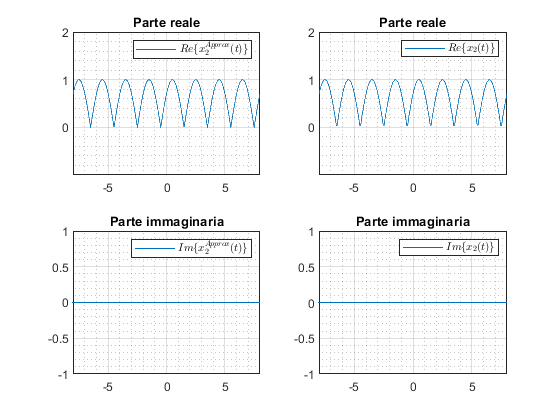

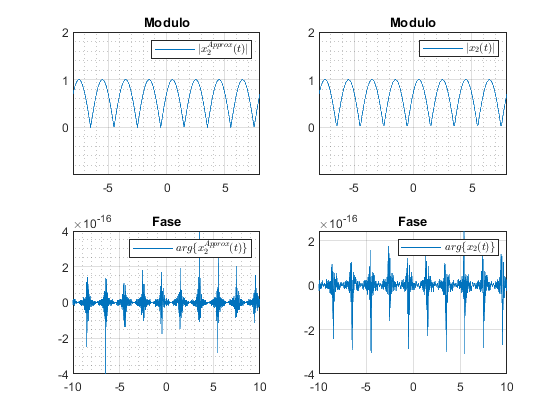

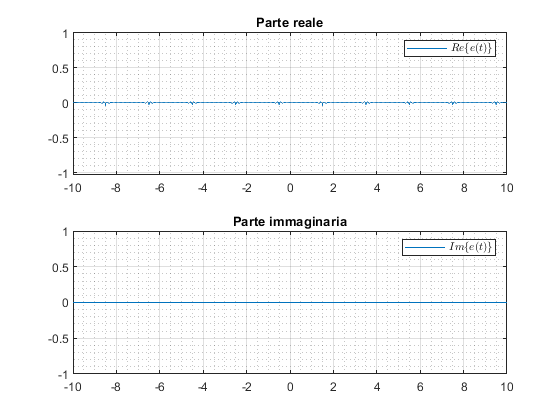

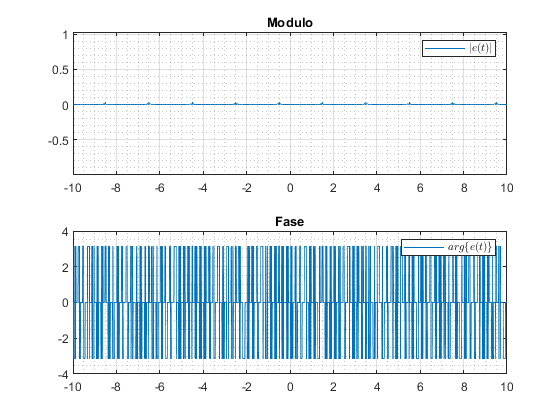

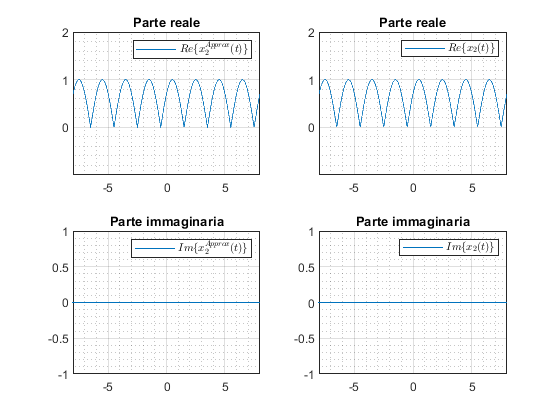

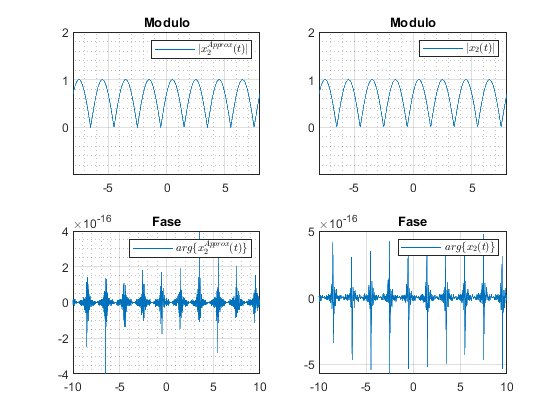

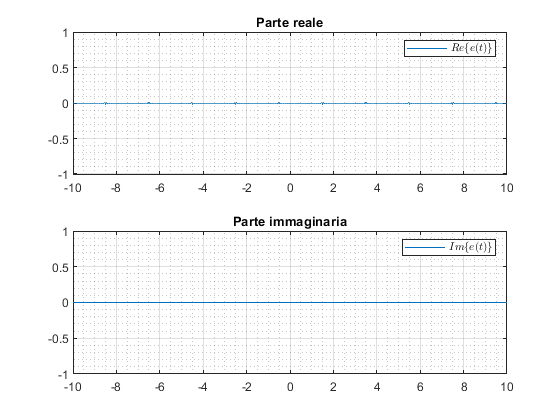

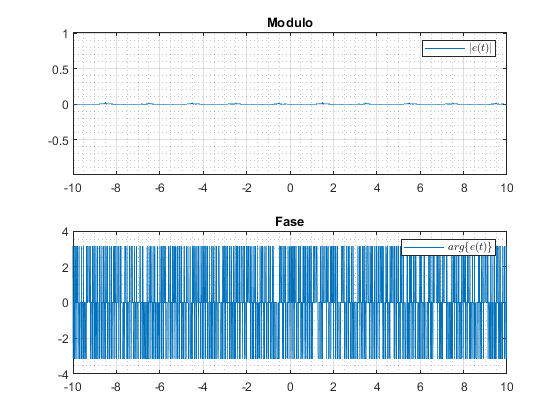

x2Approx = zeros(size(x2));
for Narm = 10:10:30
	x2Approx = serieDiFourier(t, x2, T2, 2 * Narm - 1);
	figure;
	rappresentaDueSegnali(t, x2, x2Approx, 'x_{2}^{Approx}(t)', 'x_{2}(t)');
	err = x2 - x2Approx;
	rappresentaUnSegnale(t, err, 'e(t)');
end

## Esercizio 3 (i)